# Examples of the functions

This is an example of how to use the functions of this repository.

We will use data from a 24x24 WMS placed in a 0.067 m diameter pipe in which air and oil flow together.

## Reading raw data

The** raw data** of the multiphase flow and the **calibrations files** for the oil and the air can be found in the folder /data.

We will load them with the function Cfile2Data

n=24;
RawData=Cfile2Data([pwd,'/data/twoPhase.cdat'],n);

File close successful


OilCal=Cfile2Data([pwd,'/data/oilCalibration.cdat'],n);

File close successful


AirCal=Cfile2Data([pwd,'/data/airCalibration.cdat'],n);

File close successful


We cam see how these data looks like with the function imshow

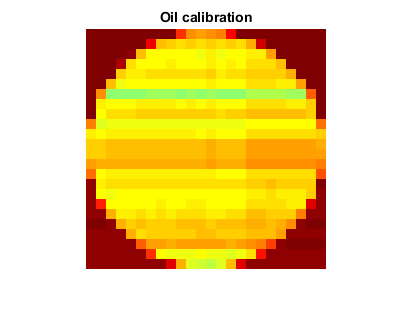

imshow(OilCal(:,:,10),[0 4095],'InitialMagnification',1000);colormap jet
title('Oil calibration')

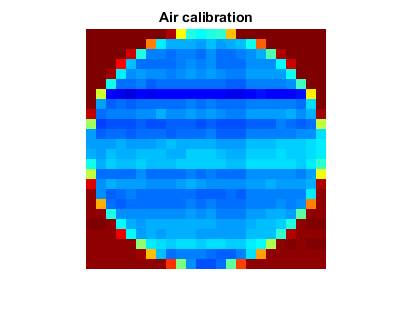

imshow(AirCal(:,:,10),[0 4095],'InitialMagnification',1000);colormap jet
title('Air calibration')

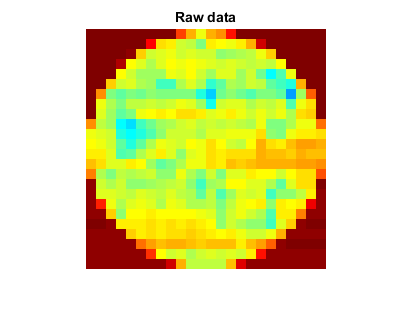

imshow(RawData(:,:,10),[0 4095],'InitialMagnification',1000);colormap jet
title('Raw data')

## Calibrating data

Before doing the calibration, we will need the** weights matrix** of the void fraction and the **mask** of the sensor. We can generate them knowing the diameter of the pipe and the number of wires in the sensor.

D=0.067;   % diameter of the pipe
n=24;      % number of wires
p=D/n ;    % distance between wires
M=weightsMatrixGenerator(D,p,n);
mask=maskGenerator(M);

And now we can see how they are distributed

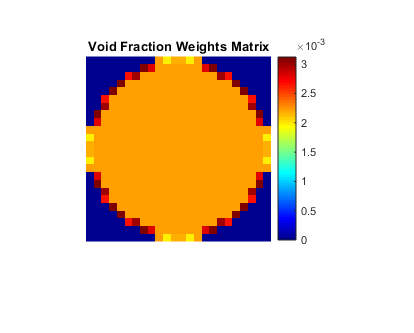

imshow(M,[0 max(max(M))],'InitialMagnification',1000);colormap jet;colorbar;
title('Void Fraction Weights Matrix')

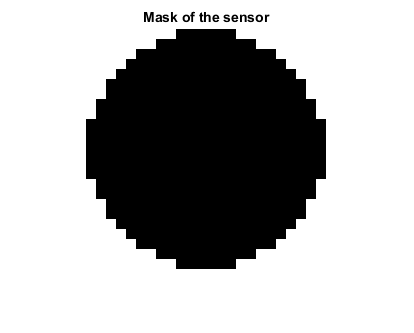

imshow(mask,[0 1],'InitialMagnification',1000);colormap gray;
title('Mask of the sensor')

Now we can proceed to do the calibration. For that, we need to know the relative permittivity of the liquid and gas phase. In this case is 1 for the air and 2.7 for the oil and the permittivity model applied is 'series'

erOil=2.7;
erAir=1;
DataVoid=calibrationPermittivity(RawData,OilCal,AirCal,mask,erOil,erAir,'series');

## Void fraction distibutions

The void fraction distribution looks like thatn in frames 10 and 1000

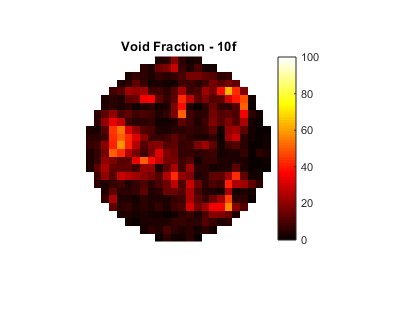

imshow(DataVoid(:,:,10),[0 100],'InitialMagnification',1000);colormap hot;colorbar;
title('Void Fraction - 10f')

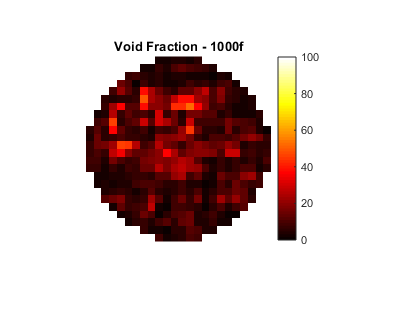

imshow(DataVoid(:,:,1000),[0 100],'InitialMagnification',1000);colormap hot;colorbar;
title('Void Fraction - 1000f')

We can also see the diametric time traces

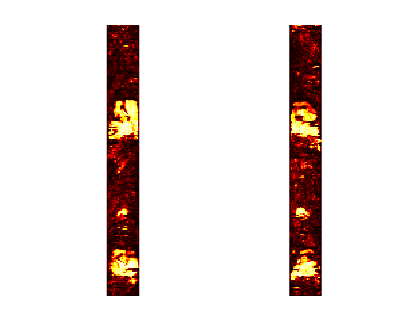

subplot(1,2,1)
imshow(squeeze(DataVoid(:,12,1:10:2000))',[0 100],'InitialMagnification',10);colormap hot
subplot(1,2,2)
imshow(squeeze(DataVoid(12,:,1:10:2000))',[0 100],'InitialMagnification',10);colormap hot

The average radial distribution of the void fraction can be calutated using the funtion Data2RadialDistribution and the radial weights matrix that must be generated first.

r=20      % is the number of division of the radial distribution

r = 20

Ra=radialWeightsMatrixGenerator(M,r);

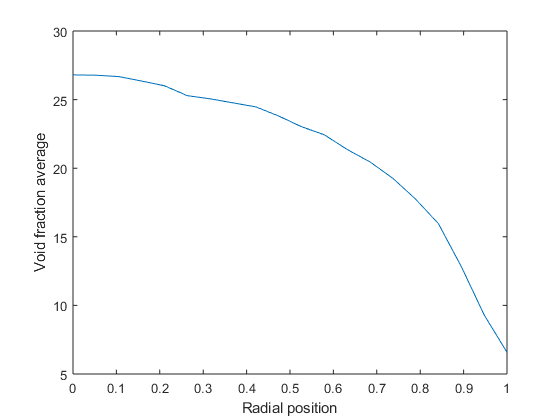

RadialDistribution=Data2RadialDistribution(DataVoid,Ra);
figure;
plot(0:1/(r-1):1,RadialDistribution)
xlabel('Radial position')
ylabel('Void fraction average')

The void fration time series in the cross-section is calculted using the function Data2TimeSeries

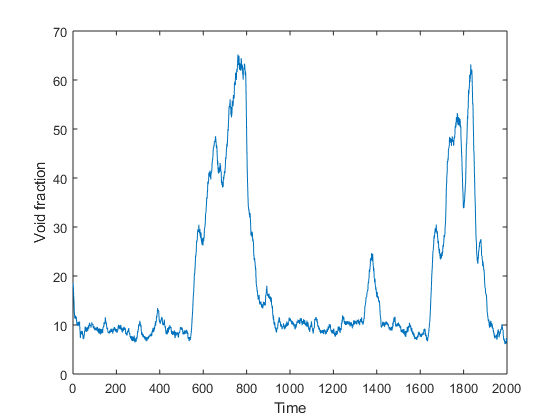

VF=Data2TimeSeries(DataVoid,M);
plot(VF)
xlabel('Time')
ylabel('Void fraction')

A probability density function of the void fraction can be now represented

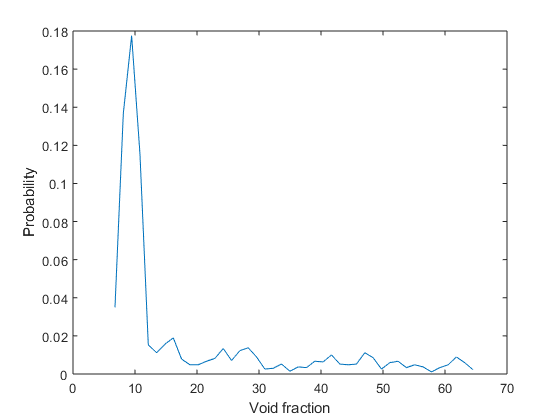

[X,N]=hist(VF,sqrt(size(VF,1)));
plot(N,X/sum(X)/(N(2)-N(1)))
xlabel('Void fraction')
ylabel('Probability')

## Rotation of the data

In some circunstances we would like to depict the void fraction images in different angle than the one at which the data was obtained. We can rotate the data using a rotation matrix generated with the code rotationMatrixGenerator and then applying it to the data with the function rotateData

% rotate the data 30 degrees
Ro_30=rotationMatrixGenerator(30,mask);
 DataVoid_30=rotateData(DataVoid(:,:,1),Ro_30,mask);
% rotate the data 100 degrees 
 Ro_100=rotationMatrixGenerator(100,mask);
 DataVoid_100=rotateData(DataVoid(:,:,1),Ro_100,mask);
% rotate the data 270 degrees 
 Ro_270=rotationMatrixGenerator(270,mask);
 DataVoid_270=rotateData(DataVoid(:,:,1),Ro_270,mask); 
 

Now we can see how the rotated data looks in the first frame for different angles

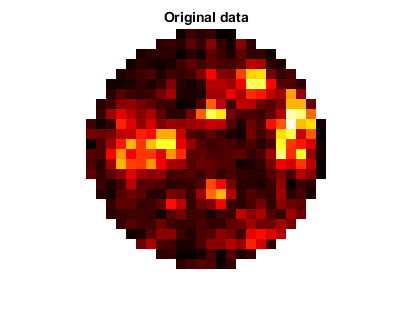

imshow(DataVoid(:,:,1),[0 100],'InitialMagnification',1000);colormap hot
title('Original data')

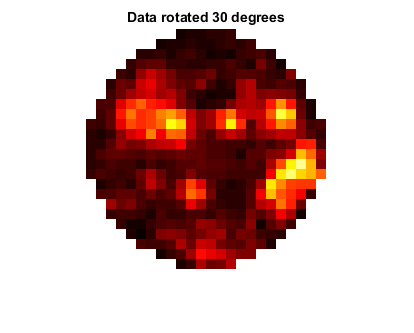

imshow(DataVoid_30(:,:,1),[0 100],'InitialMagnification',1000);colormap hot
title('Data rotated 30 degrees')

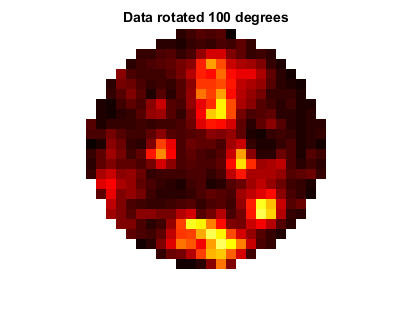

imshow(DataVoid_100(:,:,1),[0 100],'InitialMagnification',1000);colormap hot
title('Data rotated 100 degrees')

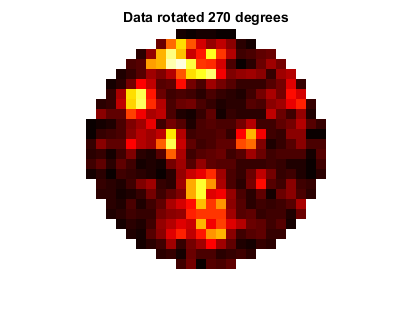

imshow(DataVoid_270(:,:,1),[0 100],'InitialMagnification',1000);colormap hot
title('Data rotated 270 degrees')

## Saving the data

Processed data can be saved into .v files. For example, we will save the calibrated void fraction data turned 100 degrees

Data2Vfile(DataVoid_100,[pwd,'/data/VoidFraction_100.v']);

ans = 0